
clear, close all





%Lets try to implement this paper


opts = odeset('RelTol',1e-2,'AbsTol',1e-2);

n = 4;

q0 = [4 4 4 4 4 4 4 4 4 4 4 4]';
qdot0 = [0 0 0 0 0 0 0 0 0 0 0 0]';

Tau = [30 60 0 0 0 0 0 0 0 0 0 30]'; %Input force

tspan = 0:.0001:.4; 
%[M_calc, C_calc, G_calc] = getMCG(4,IC1,IC2);


% Initial state
x0 = [q0; qdot0];

% Define torque input (can replace with your own controller)
%torque_func = @(t, q, q_dot) zeros(n,1);  % zero torque input
torque_func = Tau; %Constant for now
%Solve using ode15s

%[t, x] = ode15s(@(t, x) robotDynamics(t, x, n, torque_func), tspan, x0);


%Maybe try to implement my own solver
deltat = .001;
tspan2 = 0:deltat:20; 
%k1 = det(M)

% Step 1

D = 1*eye(3*n);

X_n = zeros(length(tspan2),3*n);
V_n = zeros(length(tspan2),3*n);
A_n = zeros(length(tspan2)-1,3*n);

%Implement FE solver
X_n(1,:) = q0';
V_n(1,:) = qdot0';

warning('off', 'all');

for k = 1:length(tspan2)-1
    [M, C, G] = getMCG(n, X_n(k,:)', V_n(k,:)');
    A_n(k,:) = (M\(Tau-(0*C+D)*V_n(k,:)'-G))';
    X_n(k+1,:) = (X_n(k,:)'+deltat*V_n(k,:)')';
    V_n(k+1,:) = (V_n(k,:)+deltat*A_n(k,:))';
end

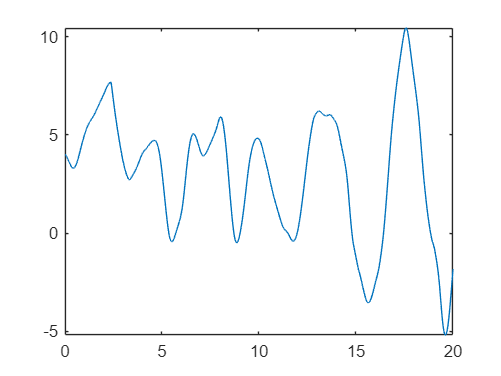


plot(tspan2,X_n(:,6))


%C3

% Extract q and q_dot
q_test = [4.01 4 4 4 3.9 4 4 4 4 4 4 4]';
d_dot_test = [0 0 0 0 0 0 2 0 0 0 0 0]';
%[M, C, G] = getMCG(n,q_test, d_dot_test);
%rank(M)
%q_sol = x(:, 1:3*n);
%qdot_sol = x(:, 3*n+1:end);
%plot(t,q_sol(:,6));



function dx = robotDynamics(t, x, n, torque_func)
    q = x(1:3*n);
    q_dot = x(3*n+1:end);

    % Get system matrices
    [M, C, G] = getMCG(n, q, q_dot);
    
    % Get torque input
    %tau = torque_func(t, q, q_dot);
    tau = torque_func;
    
    epsilon = .001;
    M_reg = M + epsilon * eye(size(M));
    %disp('---');
    %disp('M:'); disp(M_reg);
    %disp('cond(M):'); disp(cond(M_reg));
    %disp('C:'); disp(C);
    %disp('G:'); disp(G);
    %disp('T');disp(torque_func)
    % Compute acceleration
    q_ddot = M \ (tau - C*q_dot - G);

    % Return state derivative
    dx = [q_dot; q_ddot];
end    

function [M,C,G] = getMCG(n,L,dL) 
%Define number of links

%n = 4; %Try 4 for now

%I guess start by defining an inital condition?
%Start with length 4?
IC = L;

%IC = [4 4 5 5 5 5.1 4 8 8 4 6 8]';
r = 1.5; %in
m = .5; %lbm
k = 10; %lb/in?
Ke = k*eye(3*n);
Lo = 4; %in
L_o_vec = Lo*ones(3*n,1);
g = [0;0;0]; %Change this to imperial later maybe -9.81 z
Ixx = 1/4*m*r^2;

P_k = zeros(3,1,n);
R_k = zeros(3,3,n);
T_k = zeros(4,4,n);

p_bar_k = zeros(3,1, n);
R_bar_k = zeros(3,3,n);


dP_dq = zeros(3,3,n);
dP_dqT = zeros(3,3,n);
dP_dqq = cell(n,1);

dR_dq = zeros(9,3,n);
dRT_dq =zeros(9,3,n);
dR_dqT = zeros(3,9,n);

dR_dqq = cell(n,1);
dR_dqqT = cell(n,1);
dR_dqTq = cell(n,1);

dR_barq = zeros(9,3,n);
dR_barqq = cell(n,1);
dRT_barq = zeros(9,3,n);  
dR_barqT = zeros(3,9,n);


dp_barq = zeros(3,3,n);
dp_barqq = cell(n,1);
dp_barqT = zeros(3,3,n);
dR_bar_dqTq = cell(n,1);
dpi = zeros(3,3,n);
dpi_barq = zeros(3,3,n);
dpi_barqq = cell(n,1);
        
dRi_barq = zeros(9,3,n);
dRi_barqq = cell(n,1);
dpi2 = cell(n,1);
for w = 1:n
    dpi2{w} = zeros(3,3,3);
end

Ri = zeros(3,3,n);
Pi = zeros(3,1,n);
Ri_bar = zeros(3,3,n);
Pi_bar = zeros(3,1,n);

Jv_i = cell(n,1);
Hv_i = cell(n,1);
%Define Jacobian Omega
J_Omega = cell(n,1);
for w = 1:n
    J_Omega{w} = zeros(3,9*n);
end
H_Omega = cell(n,1);
for w = 1:n
    H_Omega{w} = zeros(9*n,9*n);
end
J_bar_Omega = cell(n,1);
H_bar_Omega = cell(n,1);
Jv_bar_i = cell(n,1);
Hv_bar_i = cell(n,1);


M_bar_i_omega = cell(n,1);
M_bar_i_v = cell(n,1);
M_bar_i = cell(n,1);

M_omega_i_h = cell(n,3*n);
M_v_i_h = cell(n,3*n);
M_i_h = cell(n,3*n);

%G_bar_i{i} = G_g_i{i}+G_e_i{i};
G_bar_i = cell(n,1);
G_g_i = cell(n,1);
%G_e_i = cell(n,1);

C_bar = cell(n,1);

%Given by the paper
B_v1 = 1.3155;
B_v2 = 1.5053;
B_v3 = 1.8011;
B_w1 = 1;
B_w2 =1;
B_w3 = 1.1948;

%This for loop solves for qdd, qd, and q?
for i = 1:n

    %From ICs?
    L_k1 = IC(1+3*(i-1));
    L_k2 = IC(2+3*(i-1));
    L_k3 = IC(3+3*(i-1));

    L_ck = (L_k1+L_k2+L_k3)/3;
    %One angle
    beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
    %Another angle - see paper
    theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));

    rho_k = beta_k/L_ck;


    %Compute p_i, where i is number of sections
    R_k(:,:,i) = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
        (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
        -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];

    %Code for if there is no curvature
    if rho_k == 0
        P_k(:,:,i) = [L_k1 L_k2 L_k3]';
        
        p_bar_local = [0; 0; L_ck/2];  % Aligned along local x-axis
        R_bar_i = eye(3);

    else
        P_k(:,:,i) = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
    
        % With curvature
        r_k = 1 / rho_k;
        beta_half = beta_k / 2;
        
        R_bend_half = [cos(beta_half) 0 sin(beta_half);
               0          1 0;
              -sin(beta_half) 0 cos(beta_half)];

        % Position of midpoint along circular arc in local arc plane (XZ plane)
        p_cog_plane = [r_k * (1 - cos(beta_half));
                       0;
                       r_k * sin(beta_half)];
    
        % Rotate from arc plane to actual bending plane using theta_k (rotation about Z)
        R_theta = [cos(theta_k), -sin(theta_k), 0;
                   sin(theta_k),  cos(theta_k), 0;
                        0      ,       0      , 1];
    
        p_bar_local = R_theta * p_cog_plane;
        R_bar_i = R_theta * R_bend_half;
    end

    %Transofrmation matrix
    T_k(:,:,i) = [R_k(:,:,i) P_k(:,:,i)
        0 0 0 1];
    
    %Compute pbar and Rbar i
    %Note: I feel like my R_bar calc may be slightly wrong but not sure
    R_bar_k(:,:,i) = R_bar_i;
    p_bar_k(:,:,i) = p_bar_local;
    
    
    %Compute Ri_bar
    
    %If first set, then just do eye
    if i == 1
        Ri(:,:,i) = eye(3)*R_bar_k(:,:,i);
        Pi(:,:,i) = eye(3)*P_k(:,:,1);

        Ri_bar(:,:,i) = eye(3)*R_bar_k(:,:,i);
        Pi_bar(:,:,i) = eye(3)*p_bar_k(:,:,i);
        
        

    else
        Ri(:,:,i) = Ri(:,:,i-1)*R_bar_k(:,:,i);
        Pi(:,:,i) = Pi(:,:,i-1)+Ri(:,:,i-1)*P_k(:,:,i);
        
        Ri_bar(:,:,i) = Ri(:,:,i-1)*R_bar_k(:,:,i);
        Pi_bar(:,:,i) = Pi(:,:,i-1)+Ri(:,:,i-1)*p_bar_k(:,:,i);
        
        

    end

    %Compute Partials
    dP_dq(:,:,i) = computedP_dq(L_k1,L_k2,L_k3,r);
    dP_dqT(:,:,i) = dP_dq(:,:,i)';
    dP_dqq{i} = computedP_dqq(L_k1,L_k2,L_k3,r);
    
    %COG TERMS
    dR_barq(:,:,i) = computeRbarq(L_k1,L_k2,L_k3,r);
    dR_barqq{i} = computeRbarqq(L_k1,L_k2,L_k3,r);
    dp_barq(:,:,i) = compute_pbarq(L_k1,L_k2,L_k3,r);
    dp_barqT(:,:,i) = dp_barq(:,:,i)';
    dp_barqq{i} = compute_pbarqq(L_k1,L_k2,L_k3,r);
    
    %Now convert to global
    if i == 1
        %Need this for later
        dpi(:,:,i) = dP_dq(:,:,i);
        dpi2{i} = dP_dqq{i};

        dpi_barq(:,:,i) = dp_barq(:,:,i);
        dpi_barqq{i} = dp_barqq{i};
        
        dRi_barq(:,:,i) = dR_barq(:,:,i);
        dRi_barqq{i} = dR_barqq{i};

    else
        
        %Need this for later
        dpi(:,:,i) = dpi(:,:,i-1)+Ri(:,:,i-1)*dP_dq(:,:,i);
        
        H = dpi2{i};  % 3 x 3 x 3 tensor
        % Multiply rotation R(:,:,i-1) on first dimension of each slice H(:,:,k)
        for k = 1:size(H,3)
            dpi2{i}(:,:,k) = dpi2{i}(:,:,k)+Ri(:,:,i-1) * H(:,:,k);  % 3x3 * 3x3 -> 3x3
        end
       
        %dpi2{i} = dpi2{i-1}+Ri(:,:,i-1)*dP_dqq{i};
        
        dpi_barq(:,:,i) = dpi(:,:,i)+Ri(:,:,i-1)*dp_barq(:,:,i);
        H = dp_barqq{i};  % 3 x 3 x 3 tensor
        % Multiply rotation R(:,:,i-1) on first dimension of each slice H(:,:,k)
        for k = 1:size(H,3)
            dpi_barqq{i}(:,:,k) = dpi2{i}(:,:,k)+Ri(:,:,i-1) * H(:,:,k);  % 3x3 * 3x3 -> 3x3
        end
        
        %dRi_barq(:,:,i) = Ri(:,:,i-1)*dR_barq(:,:,i);
        dRi_barq_set = zeros(9,3);
        for j = 1:3
            dRj = reshape(dR_barq(:,j,i), 3, 3);  % unflatten to 3×3
            dRj_global = Ri(:,:,i-1) * dRj;       % rotate into global frame
            dRi_barq_set(:,j) = reshape(dRj_global, 9, 1);  % flatten again
        end
        dRi_barq(:,:,i) = dRi_barq_set;
        
        %dRi_barqq{i} = Ri(:,:,i-1)*dR_barqq{i};
        dRi_barqq_set = zeros(9,3,3);
        for j = 1:3
            for k = 1:3
                d2Rjk = reshape(dR_barqq{i}(:,j,k), 3, 3);  % unflatten
                d2Rjk_global = Ri(:,:,i-1) * d2Rjk;
                dRi_barqq_set(:,j,k) = reshape(d2Rjk_global, 9, 1);  % flatten again
            end
        end
        dRi_barqq{i} = dRi_barqq_set;
    end

    R_i_q = compute_dRdq(L_k1,L_k2,L_k3,theta_k,beta_k,r);
    dR_dq(:,:,i) = R_i_q;
    
    %I now want dRT_dq and dRdqT
    % Construct commutation matrix K for 3x3 matrices (size 9x9)
    K = reshape(1:9,3,3)';
    K = K(:);
    K_mat = eye(9);
    K_mat = K_mat(K,:); % permute rows according to K to build commutation matrix
    
    % Then compute derivative of vec(R_i^T)
    dRT_dq(:,:,i) = K_mat * R_i_q;  % 9x3 matrix, derivative of vec(R_i^T)
    %COG
    dRT_barq(:,:,i) = K_mat*dR_barq(:,:,i);
    
    dR_dqT(:,:,i) = R_i_q';
    %COG
    dR_barqT(:,:,i) = dR_barq(:,:,i)';
   
    %Doubles
    R_qq = compute_d2Rdq2(L_k1,L_k2,L_k3,theta_k,beta_k,r);
    
    dR_dqq{i} = R_qq;
    % Get R_{qi,q^T_i}
    dR_dqqT{i} = permute(R_qq, [2, 1, 3]);  % Now 3 x 9 x 3
    
    % Get R_{q^T_i,qi}
    dR_dqTq{i} = permute(R_qq, [3, 1, 2]);  % Now 3 x 9 x 3
    %COG
    dR_bar_dqTq{i} = permute(dR_barqq{i}, [3, 1, 2]);
    %dR_dq2_flat(:,:,i) = reshape(dR_dq2, 9, 9); %Flatten for now?

  
    
    % Permute rows of R_i_q accordingly
    %dr_Tdq(:,:,i) = R_i_q(K, :);  % derivative of vec(R_i^T) w.r.t q_i


    %Set initals
    if i == 1
        J_Omega_old = [];
        H_Omega_prev = [];
        Jv_prev = [];
        H_v_prev = [];
    end
    
    %Compute J_omega_i
    J_Omega{i} = compute_J_Omega_i(R_k(:,:,i),J_Omega_old,dR_dq(:,:,i));
    %Compute H_i
    H_Omega{i} = compute_H_Omega_i(R_k(:,:,i), H_Omega_prev, J_Omega_old, dR_dq(:,:,i), dRT_dq(:,:,i), dR_dqT(:,:,i),dR_dqTq{i});
    %Compute Jv_i
    Jv_i{i} = compute_Jv_i(R_k(:,:,i), J_Omega_old, Jv_prev, P_k(:,:,i),dP_dqT(:,:,i));
    Hv_i{i} =  computeHv_i(H_v_prev, H_Omega_prev, Jv_prev, J_Omega_old, ...
                            P_k(:,:,i), dP_dq(:,:,i), dP_dqq{i}, R_k(:,:,i), dR_dq(:,:,i));
    
    
    %Alright now lets do the COG components
    J_bar_Omega{i} = compute_J_Omega_i(R_bar_k(:,:,i),J_Omega_old,dR_barq(:,:,i));
    H_bar_Omega{i} = compute_H_Omega_i(R_bar_k(:,:,i), H_Omega_prev, J_Omega_old, dR_barq(:,:,i), dRT_barq(:,:,i), dR_barqT(:,:,i),dR_bar_dqTq{i});
    
    Jv_bar_i{i} = compute_Jv_i(R_bar_k(:,:,i), J_Omega_old, Jv_prev, p_bar_k(:,:,i),dp_barqT(:,:,i));
    Hv_bar_i{i} =  computeHv_i(H_v_prev, H_Omega_prev, Jv_prev, J_Omega_old, ...
                            p_bar_k(:,:,i), dpi_barq(:,:,i), dpi_barqq{i}, R_bar_k(:,:,i), dR_barq(:,:,i));
    


  
    %Compute M_i components - finally?
    JwR_bar = BRM(J_Omega_old,R_bar_k(:,:,i));
    sigma_11_w = (JwR_bar'*JwR_bar);
    
    %JwR_bar'
    %dR_barqT(:,:,i)
    if i == 1
        sigma_12_w = [];
        
    else
        sigma_12_w = JwR_bar'*dR_barqT(:,:,i);
    end
    
    sigma_22_w = dR_barqT(:,:,i)'*dR_barqT(:,:,i);
    
    Matrix_before = [B_w1*sigma_11_w B_w2*sigma_12_w
                   B_w2*sigma_12_w' B_w3*sigma_22_w];
    M_t2 = T2_operator(Matrix_before); %Each of these will get zeros in bottom right
    M_bar_i_omega{i} = Ixx*M_t2;
    
    %Calcs for Mv
    Jw_p = column_BRM(J_Omega_old,p_bar_k(:,:,i));
    if i == 1
        sigma_11_v = [];
        sigma_12_v = [];
    else
        sigma_11_v = Jv_prev'*(Jv_prev+2*Jw_p)+B_v1*(Jw_p)'*Jw_p;
        sigma_12_v = (Jv_prev+B_v2*Jw_p)'*dp_barqT(:,:,i);
    end
    sigma_22_v = B_v3*dp_barqT(:,:,i)'*dp_barqT(:,:,i);
    
    M_bar_i_v{i} = m*[sigma_11_v sigma_12_v
                 sigma_12_v' sigma_22_v];
    
    M_bar_i{i} = M_bar_i_v{i} + M_bar_i_omega{i};
    
    %Done, now set G_i
    %G_g_i = m*g'*(Jv_prev+J_Omega_old*p_bar_k(:,:,i)*dp_barqT(:,:,i))
    if i == 1
        G_g_i{i} = m*g'*eye(3)*[dp_barqT(:,:,i)];
    else
        G_g_i{i} = m*g'*Ri(:,:,i-1)*[Jv_prev+Jw_p,dp_barqT(:,:,i)];
    end
    
    %G_e_i{i} = Ke*[L_k1-Lo,L_k2-Lo,L_k3-Lo]';

    G_bar_i{i} = G_g_i{i}';
    
    %Now for calculating C
    %The paper says put a for loop here
    for h = 1:3*i
        %Compute Mi,h
        if h>3*i
            M_omega_i_h{i,h} = zeros(3*i, 3*i);  % No contribution
        elseif h<=3*(i-1) % h ∈ q^{i-1} - compute using eta terms
            %Put a helper function here
            top_left_w = computen_w_11(h,R_bar_k(:,:,i),J_Omega_old,H_Omega_prev,B_w1);
            top_right_w = computen_w_12(i,h,R_bar_k(:,:,i),H_Omega_prev,dR_barq(:,:,i),B_w2);
            bottom_left_w = top_right_w';
            bottom_right_w = zeros(9,9); %nw22
            
            top_left_v = computen_v_11(i,h,p_bar_k(:,:,i),Jv_prev,J_Omega_old,H_v_prev,H_Omega_prev,B_v1);
            top_right_v = compute_v_12(i,h,p_bar_k(:,:,i),H_v_prev,H_Omega_prev,dp_barqT(:,:,i),B_v2);
            bottom_left_v = top_right_v';
            bottom_right_v = zeros(3,3);


        else % h ∈ q_i - compute using gamma terms
            top_left_w = computey_w_11(i,h,R_bar_k(:,:,i),J_Omega_old,dR_barq(:,:,i),B_w1);
            top_right_w = computey_w_12(i,h,R_bar_k(:,:,i),J_Omega_old,dR_barq(:,:,i),dR_barqq{i},B_w2);
            bottom_left_w = top_right_w';
            bottom_right_w = computey_w_22(i,h,dR_barqT(:,:,i),dR_bar_dqTq{i},B_w3);
            
            top_left_v = computey_v_11(i,h,p_bar_k(:,:,i),Jv_prev,J_Omega_old,dp_barq(:,:,i),B_v1);
            top_right_v = computey_v_12(i,h,p_bar_k(:,:,i),Jv_prev,J_Omega_old,dp_barq(:,:,i),dp_barqT(:,:,i),dp_barqq{i},B_v2);
            bottom_left_v = top_right_v';
            bottom_right_v = computey_v_22(i,h,dp_barqT(:,:,i),dp_barqq{i},B_v3);
        end
        M_omega_i_h{i,h} = Ixx*T2_operator([top_left_w, top_right_w;bottom_left_w, bottom_right_w]);
        M_v_i_h{i,h} = m*[top_left_v,top_right_v;bottom_left_v,bottom_right_v];
        M_i_h{i,h} = M_omega_i_h{i,h}+M_v_i_h{i,h};
    end
    
    %Set prevs
    H_Omega_prev = H_Omega{i};
    Jv_prev = Jv_i{i};
    J_Omega_old = J_Omega{i};
    H_v_prev = Hv_i{i};

end

%Now define some joint velocities
%IC_2 = [.1 .2 .1 -.1 .2 .3 .1 .1 .2 -.3 .1 .1]';
IC_2 = dL;
%Now compute Ci
for i = 1:n
    %Initialize a C of size 3nx3n
    C_i = zeros(3*i,3*i); %So there will be 3i rows, 3i columns to fill
    for j = 1:3*i %Row index
        sum_val = 0;
        for k = 1:3*i %Column Index
            for h = 1:3*i %Actuator Index, hmm
                %term = 0.5 * ( dM_dq[k](i,j) + dM_dq[j](i,k) - dM_dq[i](k,j) ) * qdot[k]
                %M_i_h{i,h} - This calls a 3ix3i matrix - Mi for actuator #h
                %term = M_i_h{i,h}(k,j); %This calls M(kj) for actuator h
                term = 1/2*(M_i_h{i,h}(k,j)-M_i_h{i,j}(k,h)-M_i_h{i,k}(h,j))*IC_2(h);
                sum_val = sum_val+term; %To complete the summation
            end
            C_i(j,k) = sum_val; %End of summation
        end    
    end
    %Now update C_bar_i
    C_bar{i} = C_i;
end

%TODO: fix this code later for any size n
M = M_bar_i{n}+[M_bar_i{n-1}, zeros(9,3);zeros(3,9),zeros(3,3)]+[M_bar_i{n-2},zeros(6,6);zeros(6,6),zeros(6,6)]+[M_bar_i{n-3},zeros(3,9);zeros(9,3),zeros(9,9)];
C = C_bar{n}+[C_bar{n-1}, zeros(9,3);zeros(3,9),zeros(3,3)]+[C_bar{n-2},zeros(6,6);zeros(6,6),zeros(6,6)]+[C_bar{n-3},zeros(3,9);zeros(9,3),zeros(9,9)];
%G_calc = G_1+K_e*(IC1-L_o_vec);
G = G_bar_i{n}+[G_bar_i{n-1};zeros(3,1)]+[G_bar_i{n-2};zeros(6,1)]+[G_bar_i{n-3};zeros(9,1)]+Ke*(L-L_o_vec);
end

Helper Functions

function y_v_11 = computey_v_11(i,h,p_bar,Jv_prev,Jw_prev,dPdq,B_v1)
    actnum = h-3*(i-1);
    pbar_ih = dPdq(:,actnum);

    n_minus_1 = i-1;
    Jw_pih = zeros(3, 3 * n_minus_1);
    Jw_pi = zeros(3, 3 * n_minus_1);

    %Now I want to block multiply my blocks for J and H by b_bar
    for j = 1:n_minus_1
        block_jw = Jw_prev(:, (j-1)*9+1 : j*9);     % 3 x 9
        % Break into 3 blocks of size 3x3 and apply p_i
        Jw_block = reshape(block_jw, 3, 3, 3); % Reshape into 3 blocks
        block_result1 = zeros(3, 3);
        block_result2 = zeros(3, 3);
    
        for k = 1:3
            block_result1(:,k) = Jw_block(:,:,k) * pbar_ih;
            block_result2(:,k) = Jw_block(:,:,k) * p_bar;
        end
        Jw_pih(:, (j-1)*3+1 : j*3) = block_result1;
        Jw_pi(:, (j-1)*3+1 : j*3) = block_result2;
    end
    %Gotta do this to make stuff fit
    if i == 1
        term1 = [];
        term2 = [];
    else
        term1 = 2*Jv_prev'*Jw_pih;
        term2 = 2*B_v1*Jw_pih'*Jw_pi;
    end
    y_v_11 = term1+term2;
end

function y_v_12 = computey_v_12(i,h,p_bar,Jv_prev,Jw_prev,dp_barq,dp_barqT,dp_barqq,B_v_2)

    %Gotta find Pih and piqTh
    actnum = h-3*(i-1);
    pbar_ih = dp_barq(:,actnum);
    Pbari_qT_h = dp_barqq(:, :, actnum); % 3x3 matrix, corresponds to p_{i,q^T,h}
    n_minus_1 = i-1;
    Jw_pih = zeros(3, 3 * n_minus_1);
    Jw_pi = zeros(3, 3 * n_minus_1);

    %Now I want to block multiply my blocks for J and H by b_bar
    for j = 1:n_minus_1
        block_jw = Jw_prev(:, (j-1)*9+1 : j*9);     % 3 x 9
        % Break into 3 blocks of size 3x3 and apply p_i
        Jw_block = reshape(block_jw, 3, 3, 3); % Reshape into 3 blocks
        block_result1 = zeros(3, 3);
        block_result2 = zeros(3, 3);
    
        for k = 1:3
            block_result1(:,k) = Jw_block(:,:,k) * pbar_ih;
            block_result2(:,k) = Jw_block(:,:,k) * p_bar;
        end
        Jw_pih(:, (j-1)*3+1 : j*3) = block_result1;
        Jw_pi(:, (j-1)*3+1 : j*3) = block_result2;
    end
    if i == 1
        term1 = [];
        term2 = [];
    else
        term1 = (Jv_prev+B_v_2*Jw_pi)'*Pbari_qT_h;
        term2 = B_v_2*Jw_pih'*dp_barqT;
    end
    
    y_v_12 = term1+term2;

end

function y_v_22 = computey_v_22(i,h,dp_barqT,dp_barqq,B_v_3)
    %Gotta find Pih and piqTh
    actnum = h-3*(i-1);
    Pbari_qT_h = dp_barqq(:, :, actnum); % 3x3 matrix, corresponds to p_{i,q^T,h}
    
    y_v_22 = 2*B_v_3*Pbari_qT_h'*dp_barqT;
end

function n_v_11 = computen_v_11(i,h,p_bar,Jv_prev,Jw_prev,Hv_prev,Hw_prev,B_v_1)

    %First we again need to find H
    H_vh = Hv_prev(3*(h-1)+1 : 3*h, :);
    H_wh = Hw_prev(3*(h-1)+1 : 3*h, :);
    
    n_minus_1 = i-1;
    Jw_pi = zeros(3, 3 * n_minus_1);
    Hw_pi = zeros(3, 3 * n_minus_1);
    
    %Now I want to block multiply my blocks for J and H by b_bar
    for j = 1:n_minus_1
        block_jw = Jw_prev(:, (j-1)*9+1 : j*9);     % 3 x 9
        block_Hw = H_wh(:, (j-1)*9+1 : j*9);     % 3 x 9
        % Break into 3 blocks of size 3x3 and apply p_i
        Jw_block = reshape(block_jw, 3, 3, 3); % Reshape into 3 blocks
        Hw_block = reshape(block_Hw, 3, 3, 3); % Reshape into 3 blocks
        block_result1 = zeros(3, 3);
        block_result2 = zeros(3, 3);
    
        for k = 1:3
            block_result1(:,k) = Jw_block(:,:,k) * p_bar;
            block_result2(:,k) = Hw_block(:,:,k) * p_bar;
        end
    
        Jw_pi(:, (j-1)*3+1 : j*3) = block_result1;
        Hw_pi(:, (j-1)*3+1 : j*3) = block_result2;
    end

    term1 = 2*H_vh'*(Jv_prev+Jw_pi);
    term2 = 2*Jv_prev'*Hw_pi;
    term3 = 2*B_v_1*Jw_pi'*Hw_pi;
    n_v_11 = term1+term2+term3;

end

function n_v_12 = compute_v_12(i,h,p_i,Hv_prev,Hw_prev,p_barqT,B_v_2)
    %First we again need to find H
    H_vh = Hv_prev(3*(h-1)+1 : 3*h, :);

    n_minus_1 = i-1;
    Hw_p = zeros(3, 3 * n_minus_1);

    for j = 1:(3 * n_minus_1)
        % Get the j-th 9x3 column block from Hw
        H_block = Hw_prev(:, (j-1)*3 + (1:3));  % [9*(n-1) x 3]

        % Reshape this 9*(n-1) x 3 block into (n-1) blocks of 9x3
        % and take the first 3 rows from each 9x3 block
        %temp = zeros(3, 3);
        for b = 1:n_minus_1
            % Extract 9x3 block
            H_bj = H_block((b-1)*9 + (1:9), :);

            % Break into 3x3 sub-blocks
            H1 = H_bj(1:3, :);
            H2 = H_bj(4:6, :);
            H3 = H_bj(7:9, :);

            % Multiply with p_i
            col_result = H1 * p_i(1) + H2 * p_i(2) + H3 * p_i(3); % 3x1

            % Place result in output matrix
            Hw_p(:, (b-1)*3 + (1:3)) = col_result;  % fill 3x3 block
        end
    end
   
    
    term1 = H_vh+2*B_v_2*Hw_p;
    n_v_12 = term1'*p_barqT;
end


function y_w_11 = computey_w_11(i,h,R_bar,J_prev,dRBarq,B_w_1)
    
    %If h is 12, then i is 4, 12-9 is 3
    actnum = h-3*(i-1);
    rows = (3*(actnum-1) + 1) : (3*actnum);  % select 3 rows corresponding to actuator h
    R_i_h = dRBarq(rows, :);       % R_i_h is 3x3 partial derivative matrix

    term1 = BRM(J_prev,R_i_h);
    term2 = BRM(J_prev,R_bar);
    y_w_11 = 2*B_w_1*term1'*term2;
end

function y_w_12 = computey_w_12(i,h,R_bar,J_prev,dRBarq,dRBarqq,B_w_2)
    %Need to first find Rih and Ri_q_h 
    actnum = h-3*(i-1);
    rows = (3*(actnum-1) + 1) : (3*actnum);  % select 3 rows corresponding to actuator h
    R_i_h = dRBarq(rows, :);       % R_i_h is 3x3 partial derivative matrix
    Riqh = dRBarqq(:, :, actnum);  % This gives a 9x3 matrix
    
    term1 = zeros(9, 9*(i-1));
    term2 = zeros(9, 9*(i-1));
    
    % Loop over each block of J for the two terms
    for b = 1:(i-1)
        % Indices for current 3x9 block in H_h
        col_indices = (b-1)*9 + (1:9);
        
        % Extract current block from H_h (3 x 9)
        H_block = J_prev(:, col_indices);
        
        % Multiply: (9 x 3) * (3 x 9) = (9 x 9)
        term1_block = dRBarq * H_block;
        term2_block = Riqh * H_block;
        % Assign block to output matrix
        term1(:, col_indices) = term1_block;
        term2(:, col_indices) = term2_block;
    end
    
    %Now calc
    y_w_12 = B_w_2*BRM(term2',R_bar)+BRM(term2',R_i_h);
end

function y_w_22 = computey_w_22(i,h,RiqT,dRBarqq,B_w_3)
    %Need to first find Rih and Ri_q_h 
    actnum = h-3*(i-1);
    Riqh = dRBarqq(:, :, actnum);  % This gives a 9x3 matrix
    y_w_22 = 2*B_w_3*Riqh'*RiqT;

end


function n_w_11 = computen_w_11(h,R_bar,J_prev,H_prev,B_w_1)
    term1 = BRM(J_prev,R_bar)';
    H_h = H_prev(3*(h-1)+1 : 3*h, :);
    term2 = BRM(H_h,R_bar);
    n_w_11 = 2*B_w_1*term1*term2;
    %n_w_11 = term1;
end

function n_w_12 = computen_w_12(n,h,R_bar,H_prev,dRBarq,B_w_2)
    H_h = H_prev(3*(h-1)+1 : 3*h, :);
    n12_w = zeros(9, 9*(n-1));
    
    % Loop over each block of H_h
    for b = 1:(n-1)
        % Indices for current 3x9 block in H_h
        col_indices = (b-1)*9 + (1:9);
        
        % Extract current block from H_h (3 x 9)
        H_block = H_h(:, col_indices);
        
        % Multiply: (9 x 3) * (3 x 9) = (9 x 9)
        n12_w_block = dRBarq * H_block;
        
        % Assign block to output matrix
        n12_w(:, col_indices) = n12_w_block;
    end
    term1 = n12_w;
    
    n_w_12 = B_w_2*BRM(term1',R_bar);

end

function Jw_p = column_BRM(J_omega,p_bar)
    n_blocks = size(J_omega, 2) / 9;   % Number of 3x9 blocks
    Jw_p = zeros(3, 3*n_blocks);       % Final size: 3 x 3(n-1)
    
    for k = 1:n_blocks
        % Extract 3x9 block from J_omega
        Jw_block = J_omega(:, 9*(k-1)+1 : 9*k);  % 3x9
    
        % Split into three 3x3 matrices
        J1 = Jw_block(:, 1:3);
        J2 = Jw_block(:, 4:6);
        J3 = Jw_block(:, 7:9);
    
        % Each multiplies p_bar to form one 3x3 matrix
        % Jk * p_bar is 3x1, assign each as a column
        J_block_p = [J1*p_bar, J2*p_bar, J3*p_bar];  % 3x3
    
        % Assign this 3x3 result into the proper block of Jw_p
        Jw_p(:, 3*(k-1)+1 : 3*k) = J_block_p;
    end
end

function M_t2 = T2_operator(M)
    % M is 9n x 9n composed of (3n x 3n) blocks of 3x3 matrices
    % T2_operator applies trace2 = M(1,1) + M(2,2) to each 3x3 block,
    % outputting a (3n x 3n) matrix of scalars.
    
    block_size = 3;
    N = size(M,1) / block_size; % N = 3n
    
    M_t2 = zeros(N, N);
    
    for i = 1:N
        for j = 1:N
            block = M((i-1)*block_size + (1:block_size), (j-1)*block_size + (1:block_size));
            % sum of first two diagonal elements
            M_t2(i,j) = block(1,1) + block(2,2);
        end
    end
    
    end




function result = BRM(A, R)
% rightMultiply3x3Blocks multiplies each 3x3 block of a (3m x 3n) matrix A by a 3x3 matrix R from the right.
%
% A is a (3m x 3n) matrix composed of m x n blocks of size 3x3
% R is a 3x3 matrix
% result is a (3m x 3n) matrix where each 3x3 block A_ij has been replaced by A_ij * R

    [rows, cols] = size(A);

    if mod(rows, 3) ~= 0 || mod(cols, 3) ~= 0
        error('Input matrix A must be sized 3m x 3n.');
    end

    m = rows / 3;
    n = cols / 3;

    result = zeros(rows, cols);

    for i = 1:m
        for j = 1:n
            row_idx = (i-1)*3 + 1;
            col_idx = (j-1)*3 + 1;
            block = A(row_idx:row_idx+2, col_idx:col_idx+2);  % 3x3 block
            result(row_idx:row_idx+2, col_idx:col_idx+2) = block * R;
        end
    end
end


%Calculating the partial of P
function dP_dq = computedP_dq(L1,L2,L3,r)
    % Compute intermediate variables
    L_ck = (L1 + L2 + L3) / 3;
    % Helper terms for beta_k
    A = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if A <= .1
        dP_dq = [0,0,0;0,0,0;1/3,1/3,1/3];
        return;
    end
    sqrtA = sqrt(A);
    beta_k = 2 * sqrtA / (3 * r);
    % Compute partial derivatives of A wrt L1, L2, L3
    dA_dL1 = 2*L1 - L2 - L3;
    dA_dL2 = 2*L2 - L1 - L3;
    dA_dL3 = 2*L3 - L1 - L2;
    
    % Partial derivatives of beta_k
    dbeta_dL1 = (2/(3*r)) * (0.5 / sqrtA) * dA_dL1;
    dbeta_dL2 = (2/(3*r)) * (0.5 / sqrtA) * dA_dL2;
    dbeta_dL3 = (2/(3*r)) * (0.5 / sqrtA) * dA_dL3;
    % Partial derivatives of L_ck
    dLck_dL1 = 1/3;
    dLck_dL2 = 1/3;
    dLck_dL3 = 1/3;
    % rho_k and its derivatives using quotient rule
    rho_k = beta_k / L_ck;
    drho_dL1 = (dbeta_dL1 * L_ck - beta_k * dLck_dL1) / (L_ck^2);
    drho_dL2 = (dbeta_dL2 * L_ck - beta_k * dLck_dL2) / (L_ck^2);
    drho_dL3 = (dbeta_dL3 * L_ck - beta_k * dLck_dL3) / (L_ck^2);
    
    % Compute theta_k
    numerator = 3*(L2 - L3);
    denominator = sqrt(3)*(L2 + L3 - 2*L1);
    theta_k = atan2(numerator, denominator);
    
    % Partial derivatives of numerator and denominator
    dnum_dL1 = 0;
    dnum_dL2 = 3;
    dnum_dL3 = -3;
    
    dden_dL1 = -2*sqrt(3);
    dden_dL2 = sqrt(3);
    dden_dL3 = sqrt(3);
    
    % Partial derivatives of theta_k using atan2 derivative formula
    denom_sq = denominator^2 + numerator^2;
    dtheta_dL1 = (denominator * dnum_dL1 - numerator * dden_dL1) / denom_sq;
    dtheta_dL2 = (denominator * dnum_dL2 - numerator * dden_dL2) / denom_sq;
    dtheta_dL3 = (denominator * dnum_dL3 - numerator * dden_dL3) / denom_sq;
    
    % Precompute trig functions
    cos_beta = cos(beta_k);
    sin_beta = sin(beta_k);
    cos_theta = cos(theta_k);
    sin_theta = sin(theta_k);
    
    f = 1 / rho_k;
    g = 1 - cos_beta;
    h_cos = cos_theta;
    h_sin = sin_theta;
    
    % Derivatives of f
    df_dL1 = -1 / (rho_k^2) * drho_dL1;
    df_dL2 = -1 / (rho_k^2) * drho_dL2;
    df_dL3 = -1 / (rho_k^2) * drho_dL3;
    
    % Derivatives of g
    dg_dL1 = sin_beta * dbeta_dL1;
    dg_dL2 = sin_beta * dbeta_dL2;
    dg_dL3 = sin_beta * dbeta_dL3;
    
    % Derivatives of h_cos and h_sin
    dhcos_dL1 = -sin_theta * dtheta_dL1;
    dhcos_dL2 = -sin_theta * dtheta_dL2;
    dhcos_dL3 = -sin_theta * dtheta_dL3;
    
    dhsin_dL1 = cos_theta * dtheta_dL1;
    dhsin_dL2 = cos_theta * dtheta_dL2;
    dhsin_dL3 = cos_theta * dtheta_dL3;
    
    % Compute each partial derivative of P vector wrt L1
    dP_dL1 = [df_dL1 * g * h_cos + f * dg_dL1 * h_cos + f * g * dhcos_dL1;
              df_dL1 * g * h_sin + f * dg_dL1 * h_sin + f * g * dhsin_dL1;
              df_dL1 * sin_beta + f * cos_beta * dbeta_dL1];
    
    % wrt L2
    dP_dL2 = [df_dL2 * g * h_cos + f * dg_dL2 * h_cos + f * g * dhcos_dL2;
              df_dL2 * g * h_sin + f * dg_dL2 * h_sin + f * g * dhsin_dL2;
              df_dL2 * sin_beta + f * cos_beta * dbeta_dL2];
    
    % wrt L3
    dP_dL3 = [df_dL3 * g * h_cos + f * dg_dL3 * h_cos + f * g * dhcos_dL3;
              df_dL3 * g * h_sin + f * dg_dL3 * h_sin + f * g * dhsin_dL3;
              df_dL3 * sin_beta + f * cos_beta * dbeta_dL3];
    
    % Combine into Jacobian: 3 rows (P components) x 3 cols (L variables)
    dP_dq = [dP_dL1, dP_dL2, dP_dL3];
end


function dP_dqq = computedP_dqq(L1,L2,L3,r)
    % Precompute variables
    Lck = (L1+L2+L3)/3;
    S = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if S <= .1
        dP_dqq = zeros(3,3,3);
        return
    end
    sqrtS = sqrt(S);
    beta = 2*sqrtS/(3*r);
    Y = 3*(L2 - L3);
    X = sqrt(3)*(L2 + L3 - 2*L1);
    theta = atan2(Y,X);
    rho = beta / Lck;

    % Partial derivatives of S
    dS = [2*L1 - (L2+L3);
          2*L2 - (L1+L3);
          2*L3 - (L1+L2)];
    % Second derivatives of S (constant matrix)
    d2S = 2*eye(3) - ones(3);

    % Derivatives of beta
    dbeta = (1/(3*r*sqrtS)) * dS;
    d2beta = zeros(3,3);
    for j=1:3
        for k=1:3
            term1 = -0.5/(3*r*S^(3/2)) * dS(j) * dS(k);
            term2 = (1/(3*r*sqrtS)) * d2S(j,k);
            d2beta(j,k) = term1 + term2;
        end
    end

    % Derivatives of theta
    dY = [0; 3; -3];
    dX = [-2*sqrt(3); sqrt(3); sqrt(3)];
    denom = X^2 + Y^2;
    dtheta = zeros(3,1);
    for j=1:3
        dtheta(j) = (X*dY(j) - Y*dX(j))/denom;
    end

    % Second derivatives of theta
    d2theta = zeros(3,3);
    for j=1:3
        for k=1:3
            numerator = denom*(dX(k)*dY(j) - dY(k)*dX(j)) ...
                        - 2*(X*dX(k) + Y*dY(k))*(X*dY(j) - Y*dX(j));
            d2theta(j,k) = numerator / denom^2;
        end
    end

    % Derivatives of Lck
    dLck = [1/3;1/3;1/3];

    % Derivatives of rho
    drho = (1/Lck)*dbeta - (beta/(Lck^2))*dLck;

    % Second derivatives of rho
    d2rho = zeros(3,3);
    for j=1:3
        for k=1:3
            d2rho(j,k) = (1/Lck)*d2beta(j,k) ...
                         - (1/(Lck^2))*(dbeta(k)*dLck(j) + dbeta(j)*dLck(k)) ...
                         + (2*beta/(Lck^3))*dLck(j)*dLck(k);
        end
    end

    % Compute P vector
    one_minus_cosb = 1 - cos(beta);
    sinb = sin(beta);
    P = (1/rho)*[one_minus_cosb*cos(theta);
                 one_minus_cosb*sin(theta);
                 sinb];

    % Precompute terms for dQ_dL
    dQ = zeros(3,3);
    for j=1:3
        dQ(1,j) = sin(beta)*dbeta(j)*cos(theta) + one_minus_cosb*(-sin(theta))*dtheta(j);
        dQ(2,j) = sin(beta)*dbeta(j)*sin(theta) + one_minus_cosb*cos(theta)*dtheta(j);
        dQ(3,j) = cos(beta)*dbeta(j);
    end

    % Jacobian dP/dL
    dP_dL = zeros(3,3);
    for j=1:3
        dP_dL(:,j) = (-1/(rho^2))*drho(j)*[one_minus_cosb*cos(theta); one_minus_cosb*sin(theta); sinb] + (1/rho)*dQ(:,j);
    end

    % Hessian d2P/dLdL
    dP_dqq = zeros(3,3,3);
    % Second derivatives of Q
    for i=1:3
        for j=1:3
            for k=1:3
                % d2Q_i/(dL_j dL_k)
                switch i
                    case 1
                        term1 = cos(theta)*(cos(beta)*dbeta(k)*dbeta(j) + sin(beta)*d2beta(j,k));
                        term2 = sin(beta)*dbeta(j)*(-sin(theta))*dtheta(k);
                        term3 = one_minus_cosb*(-cos(theta))*dtheta(k)*dtheta(j);
                        term4 = one_minus_cosb*(-sin(theta))*d2theta(j,k);
                        d2Q = term1 + term2 + term3 + term4;
                    case 2
                        term1 = sin(theta)*(cos(beta)*dbeta(k)*dbeta(j) + sin(beta)*d2beta(j,k));
                        term2 = sin(beta)*dbeta(j)*cos(theta)*dtheta(k);
                        term3 = one_minus_cosb*(-sin(theta))*dtheta(k)*dtheta(j);
                        term4 = one_minus_cosb*cos(theta)*d2theta(j,k);
                        d2Q = term1 + term2 + term3 + term4;
                    case 3
                        d2Q = -sin(beta)*dbeta(k)*dbeta(j) + cos(beta)*d2beta(j,k);
                end
                % Compose Hessian element
                dP_dqq(i,j,k) = 2*(1/(rho^3))*drho(k)*drho(j)*P(i) ...
                                 - (1/(rho^2))*d2rho(j,k)*P(i) ...
                                 - (1/(rho^2))*drho(j)*dP_dL(i,k) ...
                                 - (1/(rho^2))*drho(k)*dP_dL(i,j) ...
                                 + (1/rho)*d2Q;
            end
        end
    end

end

function J_Omega_i = compute_J_Omega_i(R_i, J_Omega_prev, dR_dq)

    % Case: base link (no previous Jacobian)
    if isempty(J_Omega_prev)
        J_rotated = [];
    else
        % Multiply each 3x3 block of J_Omega_prev on the right by R_i
        J_rotated = block_right_multiply(J_Omega_prev, R_i, 3);  % size: 3 x 9(n-1)
    end

    % Now add current segment block
    % dR_dq is 9x3, but we want it as 3x9 (for concatenation)
    J_current = reshape(dR_dq, 3, 9);  % vector-to-matrix conversion

    % Concatenate horizontally
    J_combined = [J_rotated, J_current];  % size: 3 x 9n

    % Rotate the entire thing from body to world frame
    J_Omega_i = R_i.' * J_combined;  % final size: 3 x 9n
end


%Compute first derivative of R wrt q
function dR_dq = compute_dRdq(L_k1,L_k2,L_k3,theta_k,beta_k,r)

    %Compute Partials
    f = L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3;
    if f <= .1
    % No bending, beta_k = 0
        %dbeta_dL = zeros(3,1);
        hat_z = [0 -1 0
                 1 0 0
                 0 0 0];
        dRdq1 = 0 * hat_z;
        dRdq2 = 1 * hat_z;
        dRdq3 = -1 * hat_z;
        dR_dq = 2*[reshape(dRdq1,9,1), reshape(dRdq2,9,1), reshape(dRdq3,9,1)];
        return
    else
        dbeta_dL = (1 / (3 * r * sqrt(f))) * [2*L_k1 - L_k2 - L_k3;
                                              2*L_k2 - L_k1 - L_k3;
                                              2*L_k3 - L_k1 - L_k2];
    
    end    
    y = 3 * (L_k2 - L_k3);
    x = sqrt(3) * (L_k2 + L_k3 - 2 * L_k1);
    denom = x^2 + y^2;
    dx_dq = [-2*sqrt(3); sqrt(3); sqrt(3)];
    dy_dq = [0; 3; -3];

    if denom <= .1
        % theta_k undefined when straight; set derivatives zero or handle specially
        dtheta_dL = zeros(3,1);
    else
        dtheta_dL = (1 / denom) * (dy_dq * x - y * dx_dq);
    end
    
    % Derivatives
    
    
    % Trig terms
    cb = cos(beta_k); sb = sin(beta_k);
    ct = cos(theta_k); st = sin(theta_k);

    % Partial of R w.r.t. beta
    dR_dbeta = [ -sb * ct^2,         (-1 * sb) * ct * st,       ct * cb;
                 (-1 * sb) * ct * st,  -sb * st^2,               st * cb;
                 -ct * cb,            -st * cb,                 -sb ];

    % Partial of R w.r.t. theta
    dR_dtheta = [ -2 * cb * ct * st + 2 * st * ct,     (-1 + cb)*(ct^2 - st^2),    -sb * st;
                  (-1 + cb)*(ct^2 - st^2),             2 * cb * st * ct - 2 * st * ct,  sb * ct;
                  sb * st,                             -sb * ct,                    0 ];

    %dR_dbeta_vec = reshape(dR_dbeta, 9, 1);
    %dR_dtheta_vec = reshape(dR_dtheta, 9, 1);
    
    dR_dq = zeros(9,3);
    
    for k = 1:3
        dRk = dR_dbeta * dbeta_dL(k) + dR_dtheta * dtheta_dL(k);  % 3x3
        dR_dq(:,k) = reshape(dRk, 9, 1);  % vectorize 3x3
    end
% Now dR_dq is 9x3

end

%Compute Second derivative

function d2R_dq2 = compute_d2Rdq2(L1, L2, L3, theta_k, beta_k, r)
    % Trig values
    cb = cos(beta_k); sb = sin(beta_k);
    ct = cos(theta_k); st = sin(theta_k);

    % First partials of R (3x3)
    dR_dbeta = [ -sb * ct^2,           (-sb) * ct * st,         ct * cb;
                 (-sb) * ct * st,      -sb * st^2,              st * cb;
                 -ct * cb,             -st * cb,                -sb ];

    dR_dtheta = [ -2 * cb * ct * st + 2 * st * ct,   (-1 + cb)*(ct^2 - st^2),    -sb * st;
                  (-1 + cb)*(ct^2 - st^2),           2 * cb * st * ct - 2 * st * ct,  sb * ct;
                   sb * st,                         -sb * ct,                     0 ];

    % Flattened versions (9x1)
    dR_dbeta_vec = reshape(dR_dbeta, 9, 1);
    dR_dtheta_vec = reshape(dR_dtheta, 9, 1);
    
    %Compute partials
    f = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if f <= .1
    % No bending, beta_k = 0
        dbeta_dL = zeros(3,1);
    else
        dbeta_dL = (1 / (3 * r * sqrt(f))) * [2*L1 - L2 - L3;
                                              2*L2 - L1 - L3;
                                              2*L3 - L1 - L2];
    
    end    
    y = 3 * (L2 - L3);
    x = sqrt(3) * (L2 + L3 - 2 * L1);
    denom = x^2 + y^2;
    dx_dq = [-2*sqrt(3); sqrt(3); sqrt(3)];
    dy_dq = [0; 3; -3];

    if denom <= .1
        % theta_k undefined when straight; set derivatives zero or handle specially
        dtheta_dL = zeros(3,1);
    else
        dtheta_dL = (1 / denom) * (dy_dq * x - y * dx_dq);
    end

    % First derivatives of beta and theta
    %[dbeta_dL, dtheta_dL] = compute_dR_partials(L1, L2, L3, theta_k, beta_k, r);  % same as you already wrote
    H_beta = compute_d2beta_dL2(L1, L2, L3, r);     % 3x3
    H_theta = compute_d2theta_dL2(L1, L2, L3);      % 3x3

    % Second-order derivative tensor (9x3x3)
    d2R_dq2 = zeros(9, 3, 3);
    for i = 1:3
        for j = 1:3
            term_beta = H_beta(i,j) * dR_dbeta_vec;
            term_theta = H_theta(i,j) * dR_dtheta_vec;
            term_mixed = (dbeta_dL(i) * dR_dbeta_vec) * dtheta_dL(j) + ...
                         (dtheta_dL(i) * dR_dtheta_vec) * dbeta_dL(j);  % mixed partial symmetry

            d2R_dq2(:, i, j) = term_beta + term_theta + term_mixed;
        end
    end
end

%Help with computing second derivative
function H_beta = compute_d2beta_dL2(L1, L2, L3, r)
    f = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if f <= .1
        H_beta = zeros(3,3);
        return;
    end

    denom = 2 * r * (f)^(3/2);
    H_beta = [ (L2^2 - 2*L2*L3 + L3^2),    (-L1*L2 + L1*L3 + L2*L3 - L3^2),   (L1*L2 - L1*L3 - L2^2 + L2*L3);
              (-L1*L2 + L1*L3 + L2*L3 - L3^2),  (L1^2 - 2*L1*L3 + L3^2),   (-L1^2 + L1*L2 + L1*L3 - L2*L3);
              (L1*L2 - L1*L3 - L2^2 + L2*L3),   (-L1^2 + L1*L2 + L1*L3 - L2*L3),  (L1^2 - 2*L1*L2 + L2^2)];
    H_beta = H_beta / denom;
end

function H_theta = compute_d2theta_dL2(L1, L2, L3)
    sqrt3 = sqrt(3);
    x = sqrt3 * (L2 + L3 - 2*L1);
    y = 3 * (L2 - L3);
    D = x^2 + y^2;

    if D <= .1
        H_theta = zeros(3,3);
        return;
    end

    % Precompute for readability
    D2 = D^2;

    H_theta = zeros(3,3);

    H_theta(1,1) = 8*sqrt3*(L2 - L3)*(-2*L1 + L2 + L3)/D2;
    H_theta(1,2) = 2*sqrt3*(3*(L2 - L3)^2 + 4*(L2 - L3)*(L1 - 2*L2 + L3) + x^2)/D2;
    H_theta(1,3) = 2*sqrt3*(-3*(L2 - L3)^2 + 4*(L2 - L3)*(L1 + L2 - 2*L3) - x^2)/D2;

    H_theta(2,1) = 2*sqrt3*(4*(-L1 + L3)*x - 3*(L2 - L3)^2 - x^2)/D2;
    H_theta(2,2) = 8*sqrt3*(-L1 + L3)*(L1 - 2*L2 + L3)/D2;
    H_theta(2,3) = 2*sqrt3*(4*(-L1 + L3)*(L1 + L2 - 2*L3) + 3*(L2 - L3)^2 + x^2)/D2;

    H_theta(3,1) = 2*sqrt3*(4*(L1 - L2)*x + 3*(L2 - L3)^2 + x^2)/D2;
    H_theta(3,2) = 2*sqrt3*(4*(L1 - L2)*(L1 - 2*L2 + L3) - 3*(L2 - L3)^2 - x^2)/D2;
    H_theta(3,3) = 8*sqrt3*(L1 - L2)*(L1 + L2 - 2*L3)/D2;
end

%Function for block multiplicaiton

function C = block_right_multiply(A, B, block_size)
    % Multiply each block in A on the right by B
    if isempty(A)
        C = [];
        return;
    end

    [mA, nA] = size(A);
    assert(mod(nA, block_size) == 0, 'A columns must be divisible by block_size.');
    assert(size(B,1) == block_size && size(B,2) == block_size, 'B must be square of block_size.');

    n_blocks = nA / block_size;
    C = zeros(mA, nA);

    for i = 1:n_blocks
        idx = (i-1)*block_size+1 : i*block_size;
        C(:, idx) = A(:, idx) * B;
    end
end


%Function for computing H
function H_omega_i = compute_H_Omega_i(R_i, H_Omega_prev, J_Omega_prev, dR_dq, dRT_dq, dR_dqT,dR_dqTq)
    
    n_prev = size(H_Omega_prev,1) / 9;  % n-1
    % Create block diagonal matrix of R_i repeated n-1 times
    R_block = kron(eye(n_prev), kron(R_i, R_i));  % 9(n-1) x 9(n-1)
    
    % Calculate the product
    Top_Left = R_block' * H_Omega_prev * R_block;  % size 9(n-1) x 9(n-1)
    
    %Create Zero matrix for top right
    if n_prev == 0
        Top_Right = [];
    else
        Top_Right = zeros(9*n_prev,9);
    end
    
    %Bottom Left
    % Step 1: block multiply J_Omega_prev (3x9n_prev) by R_i (3x3) block-wise
    J_rotated = zeros(3, 9 * n_prev);
    for j = 1:n_prev
        J_block = J_Omega_prev(:, 9*(j-1)+1 : 9*j);  % 3 x 9 block
        % Each 9 columns represent 3 blocks of 3 columns each
        % Multiply each 3x3 block inside J_block by R_i
        J_rotated_block = zeros(3, 9);
        for k = 0:2
            J_subblock = J_block(:, 3*k+1 : 3*(k+1));  % 3 x 3
            J_rotated_block(:, 3*k+1 : 3*(k+1)) = J_subblock * R_i;  % 3 x 3
        end
        J_rotated(:, 9*(j-1)+1 : 9*j) = J_rotated_block;
    end

    % Step 2: Multiply dRT_dq (9x3) by J_rotated (3 x 9*n_prev)
    term1 = dRT_dq * J_rotated;  % 9 x 9*n_prev
    
    
    % Step 1: Extract 3 derivative rotation blocks dR_dq: (9 x 3)
    R_q_blocks = zeros(3, 3, 3);  % 3 x 3 x 3
    for k = 1:3
        R_q_blocks(:, :, k) = reshape(dR_dq(:, k), 3, 3);
    end
    
    % Step 2: Initialize partial_mult as 9 x (9 * n_prev)
    partial_mult = zeros(9, 9 * n_prev);
    
    % Step 3: Compute block products
    for j = 1:n_prev
        J_block = J_Omega_prev(:, 9*(j-1)+1 : 9*j);  % 3 x 9
    
        for k = 0:2  % for each 3x3 block inside J_block
            sub_J = J_block(:, 3*k+1 : 3*(k+1));            % 3 x 3
            result = sub_J * R_q_blocks(:, :, k+1);         % 3 x 3
    
            % Place result in the correct location in partial_mult
            row_start = 3 * k + 1;
            col_start = 9*(j-1) + 3*k + 1;
            partial_mult(row_start:row_start+2, col_start:col_start+2) = result;
        end
    end
    
    % Step 4: Final multiplication with R_i^T
    R_i_kron = kron(eye(3), R_i');  % 9 x 9
    term2 = R_i_kron * partial_mult;  % 9 x (9*n_prev)
    
    Bottom_Left =  term1+term2;


    %Now finally do bottom right
    result_blocks = zeros(3, 9, 3);
    for k = 1:3
        % Multiply R_i^T (3x3) by dR_dqTq(:,:,k) (3x9)
        % Note: R_i' * RiqTqi(:,:,k) -> (3x3) * (3x9) = 3x9
        result_blocks(:, :, k) = R_i' * squeeze(dR_dqTq(:, :, k));
    end
    % Stack vertically: each block 3x9 → final 9x9
    term = reshape(permute(result_blocks, [1,3,2]), 9, 9);
    
    Bottom_Right = dRT_dq*dR_dqT + term;


    H_omega_i = [Top_Left Top_Right
                 Bottom_Left Bottom_Right];

end

function Jv_i = compute_Jv_i(R_i, J_Omega_prev, Jv_prev, p_i,dpdq_i)

    n_prev = size(Jv_prev, 2) / 3;
    Jv_aug = Jv_prev;
    for k = 1:n_prev
        idx = (k-1)*9;
        Jw_block = [ ...
            J_Omega_prev(:, idx + 1), ...
            J_Omega_prev(:, idx + 2), ...
            J_Omega_prev(:, idx + 3) ...
        ];  % 3x3 rotational Jacobian for segment k

        Jv_aug(:, 3*(k-1)+1 : 3*k) = Jv_aug(:, 3*(k-1)+1 : 3*k) + Jw_block * p_i;
    end

    % Append dpdq_i block
    Jv_combined = [Jv_aug, dpdq_i];

    % Rotate
    Jv_i = R_i' * Jv_combined;
end


function bigMat = vecBlocks(M)
    % M is 3 x 3*(n-1), n_blocks = 3*(n-1)/3 = n-1
    n_blocks = size(M, 2) / 3;  
    bigMat = zeros(9, size(M, 2)); % 9 x 3*(n-1)

    for k = 1:n_blocks
        block = M(:, (k-1)*3 + (1:3));  % 3x3 block
        vec_block = reshape(block, 9, 1); % 9x1 vectorized block
        bigMat(:, (k-1)*3 + (1:3)) = repmat(vec_block, 1, 3); 
        % replicate vec_block 3 times horizontally to fill 3 columns
    end
end

function Hv_i = computeHv_i(Hv_prev, Homega_prev, J_v_prev, Jw_prev, ...
                            p_i, dpdq_i, d2pdq2_i, R_i, dRT_dq_i)
    n_prev = size(Hv_prev, 2) / 3;  % number of previous segments

    
    % Create a 9*(n_prev) x 3*(n_prev) matrix where each 9x3 block on diag is p_i repeated 3 times vertically
    p_block = repmat(p_i, 3, 1);             % 9 x 1
    P_big = kron(eye(n_prev), p_block);      % 9*n_prev x n_prev (each column is p_block)

    % We want to multiply Homega_prev (9*n_prev x 9*n_prev) by P_big (9*n_prev x n_prev) => 9*n_prev x n_prev
    Homega_p = Homega_prev * P_big;          % 9*n_prev x n_prev

    % Now, expand Homega_p horizontally to match Hv_prev (9*n_prev x 3*n_prev)
    Homega_p_exp = kron(Homega_p, ones(1,3)); % 9*n_prev x 3*n_prev

    sum_term = Hv_prev + Homega_p_exp;       % 9*n_prev x 3*n_prev

    top_left = zeros(size(sum_term));

    for k = 1:n_prev
        rows = (k-1)*9 + (1:9);
        cols = (k-1)*3 + (1:3);
        for block = 0:2
            r = rows(1) + block*3 : rows(1) + block*3 + 2;
            top_left(r, cols) = R_i' * sum_term(r, cols);
        end
    end
    
    top_right = zeros(9 * (n_prev), 3);  % 9(n-1) x 3
    
    
    

    %bottom_left = zeros(9,3*(n_prev));
    % Compute Jw_p = Jw_prev * p_i, block-wise
    if isempty(J_v_prev) || isempty(Jw_prev)
        % No previous segments => bottom left is empty with correct size
        bottom_left = zeros(9, 0);  % 9 x 3*(0) = 9 x 0
    else
   
        Jw_p = zeros(3, 3 * n_prev);
        for k = 1:n_prev
            Jw_block = Jw_prev(:, (k-1)*9 + (1:9));         % 3 x 9
            Jw_block_reshaped = reshape(Jw_block, 3, 3, 3); % 3 x 3 x 3
    
            temp = zeros(3, 3);
            for j = 1:3
                temp(:, j) = Jw_block_reshaped(:, :, j) * p_i;  % 3 x 1 vector
            end
    
            Jw_p(:, (k-1)*3 + (1:3)) = temp;  % 3 x 3*n_prev
        end
    
        % Compute Jw_piq = Jw_prev * dpdq_i, block-wise
        Jw_piq = zeros(3, 3 * n_prev);
        for k = 1:n_prev
            Jw_block = Jw_prev(:, (k-1)*9 + (1:9));         % 3 x 9
            Jw_block_reshaped = reshape(Jw_block, 3, 3, 3); % 3 x 3 x 3
    
            temp = zeros(3, 3);
            for j = 1:3
                temp(:, j) = Jw_block_reshaped(:, :, j) * dpdq_i(:, j);  % multiply by each col of dpdq_i
            end
    
            Jw_piq(:, (k-1)*3 + (1:3)) = temp;  % 3 x 3*n_prev
        end

        bottom_left = dRT_dq_i * (J_v_prev + Jw_p) + vecBlocks(R_i' * Jw_piq);
    end
    bottom_right = zeros(9,3);
    for j = 1:3
        dpdq_col = dpdq_i(:, j);                  % 3x1
        d2p_block = d2pdq2_i(:, :, j);            % 3x3
    
        term1 = dRT_dq_i * dpdq_col;              % (3x9)' * (3x1) = 9x1
        term2 = R_i' * d2p_block;                 % 3x3
        bottom_right(:, j) = term1 + term2(:);    % 9x1
    end

    %% === Assemble final Hessian ===
    Hv_i = [top_left top_right
            bottom_left bottom_right];

end


function R_barq = computeRbarq(L1,L2,L3,r)
    % Inputs: L1, L2, L3, r (constant radius)
    %q = [L1; L2; L3];
    %L_ck = sum(q)/3;
    
    % Compute s for beta
    s = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if s <= .1
        
        hat_z = [0 -1 0
                 1 0 0
                 0 0 0];
        dRdq1 = 0 * hat_z;
        dRdq2 = 1 * hat_z;
        dRdq3 = -1 * hat_z;
        R_barq = [reshape(dRdq1,9,1), reshape(dRdq2,9,1), reshape(dRdq3,9,1)];
        
        %R_barq = zeros(9,3);
        return
    end
    beta = 2*sqrt(s)/(3*r);
    theta = atan2(3*(L2-L3), sqrt(3)*(L2 + L3 - 2*L1));
    
    % Precompute reusable terms
    phi = beta/2;
    cos_theta = cos(theta); sin_theta = sin(theta);
    cos_phi = cos(phi); sin_phi = sin(phi);
    
    % Base rotation matrices
    R_theta = [cos_theta -sin_theta 0;
               sin_theta  cos_theta 0;
               0          0         1];
    
    R_bendhalf = [cos_phi 0 sin_phi;
                  0       1 0;
                 -sin_phi 0 cos_phi];
    
    % Derivatives of base rotations wrt angles
    dR_theta_dtheta = [-sin_theta -cos_theta 0;
                        cos_theta -sin_theta 0;
                        0         0         0];
    
    dR_bendhalf_dbeta = 0.5 * [-sin_phi 0 cos_phi;
                               0        0 0;
                              -cos_phi 0 -sin_phi];
    
    % Compute partial derivatives of s wrt q
    ds_dL1 = 2*L1 - L2 - L3;
    ds_dL2 = 2*L2 - L1 - L3;
    ds_dL3 = 2*L3 - L1 - L2;
    ds_dq = [ds_dL1; ds_dL2; ds_dL3];
    
    % Partial derivatives of beta wrt q
    dbeta_dq = (2/(3*r)) * (0.5 / sqrt(s)) * ds_dq; % = (1/(3*r*sqrt(s))) * ds_dq
    
    % Partial derivatives of theta wrt q
    num = 3*(L2 - L3);
    den = sqrt(3)*(L2 + L3 - 2*L1);
    
    dnum_dq = [0; 3; -3];
    dden_dq = sqrt(3)*[-2; 1; 1];
    
    % Derivative of atan2(num, den):
    dtheta_dq = (den * dnum_dq - num * dden_dq) ./ (den^2 + num^2);
    
    % Initialize partial derivative tensors (3x3x3)
    dRbar_dq = zeros(3,3,3);
    
    for j=1:3
        dRbar_dq(:,:,j) = dR_theta_dtheta * dtheta_dq(j) * R_bendhalf + ...
                          R_theta * dR_bendhalf_dbeta * dbeta_dq(j);
    end
    R_barq = zeros(9,3);
    for j = 1:3
        R_barq(:,j) = reshape(dRbar_dq(:,:,j), 9, 1);
    end

end

function R_barqq = computeRbarqq(L1,L2,L3,r)

    % Inputs:
    %   L1, L2, L3 - segment lengths
    %   r - bending radius parameter
    
    %% Step 0: Precompute useful quantities
    
    % s and derivatives
    s = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if s <= .1
        R_barqq = zeros(9,3,3);
        return
    end
    ds_dq = [2*L1 - L2 - L3;
             2*L2 - L1 - L3;
             2*L3 - L1 - L2];
    H_s = [2 -1 -1;
           -1 2 -1;
           -1 -1 2];
       
    % beta
    beta = 2/(3*r) * sqrt(s);
    
    % derivatives of beta
    dbeta_dq = zeros(3,1);
    for j=1:3
        dbeta_dq(j) = (1/(3*r*sqrt(s))) * ds_dq(j);
    end
    
    d2beta_dq2 = zeros(3,3);
    for j=1:3
        for k=1:3
            d2beta_dq2(j,k) = (1/(3*r)) * ( ...
                -0.5 * (ds_dq(j)*ds_dq(k)) / s^(3/2) + ...
                H_s(j,k) / sqrt(s) );
        end
    end
    
    % theta
    num = 3*(L2 - L3);
    den = sqrt(3)*(L2 + L3 - 2*L1);
    theta = atan2(num, den);
    
    % derivatives of num and den
    dnum_dq = [0; 3; -3];
    dden_dq = [-2*sqrt(3); sqrt(3); sqrt(3)];
    
    % denominator squared for theta derivative
    denom2 = den^2 + num^2;
    
    % first derivatives of theta
    dtheta_dq = zeros(3,1);
    for j=1:3
        dtheta_dq(j) = (den * dnum_dq(j) - num * dden_dq(j)) / denom2;
    end
    
    % Precompute second derivatives of theta
    % Using quotient rule for second derivatives of atan2
    
    % Precompute repeated terms
    %dden_num = den * dnum_dq - num * dden_dq;
    
    d2theta_dq2 = zeros(3,3);
    for j=1:3
        for k=1:3
            % Partial derivatives of numerator
            dnum_j = dnum_dq(j);
            dnum_k = dnum_dq(k);
            dden_j = dden_dq(j);
            dden_k = dden_dq(k);
            
            % Second derivatives of numerator and denominator are zero (linear in L)
            % So only numerator is differentiated wrt q_k in the first derivative
            
            % numerator of theta derivative
            numerator_j = den * dnum_j - num * dden_j;
            
            % derivative of numerator_j w.r.t q_k
            %dnum_k_q = 0; % derivatives of dnum are zero
            %dden_k_q = 0; % derivatives of dden are zero
            %dnum_den_k = dden_k * dnum_j + den * dnum_k_q; % but dnum_k_q=0
            %dnum_num_k = dnum_k * (-dden_j) + (-num) * dden_k_q; % also 0
            
            % Actually numerator_j derivative w.r.t q_k:
            % d/dq_k [den*dnum_j - num*dden_j] = dden_k*dnum_j - dnum_k*dden_j
            dnumerator_j_dqk = dden_k * dnum_j - dnum_k * dden_j;
            
            % Now compute second derivative of theta using quotient rule:
            d2theta_dq2(j,k) = ( ...
                denom2 * dnumerator_j_dqk - ...
                2 * (den * dnum_k - num * dden_k) * numerator_j ) / denom2^2;
        end
    end
    
    %% Step 3: Rotation matrices
    
    phi = beta / 2;
    
    % R_theta (rotation about z)
    R_theta = [cos(theta), -sin(theta), 0;
               sin(theta),  cos(theta), 0;
               0        ,   0        , 1];
    
    % First derivative of R_theta w.r.t theta
    dR_theta_dtheta = [-sin(theta), -cos(theta), 0;
                        cos(theta), -sin(theta), 0;
                        0         , 0          , 0];
    
    % Second derivative of R_theta w.r.t theta
    d2R_theta_dtheta2 = [-cos(theta), sin(theta), 0;
                         -sin(theta), -cos(theta), 0;
                          0         , 0          , 0];
    
    % R_bend_half (rotation about y)
    R_bend_half = [cos(phi), 0, sin(phi);
                   0      , 1, 0;
                  -sin(phi), 0, cos(phi)];
    
    % First derivative of R_bend_half w.r.t beta (chain rule: d/dβ = 0.5 d/dφ)
    dR_bendhalf_dbeta = 0.5 * [-sin(phi), 0, cos(phi);
                                0      , 0, 0;
                               -cos(phi), 0, -sin(phi)];
    
    % Second derivative of R_bend_half w.r.t beta
    d2R_bendhalf_dbeta2 = 0.25 * [-cos(phi), 0, -sin(phi);
                                  0       , 0, 0;
                                  sin(phi), 0, -cos(phi)];
    
    %% Step 4: Compute Hessian d2Rbar/dqj dqk
    
    d2Rbar_dq2 = zeros(3,3,3,3);
    
    for j=1:3
        for k=1:3
            term1 = d2R_theta_dtheta2 * dtheta_dq(k) * dtheta_dq(j) * R_bend_half;
            term2 = dR_theta_dtheta * d2theta_dq2(j,k) * R_bend_half;
            term3 = dR_theta_dtheta * dtheta_dq(j) * dR_bendhalf_dbeta * dbeta_dq(k);
            term4 = dR_theta_dtheta * dtheta_dq(k) * dR_bendhalf_dbeta * dbeta_dq(j);
            term5 = R_theta * d2R_bendhalf_dbeta2 * dbeta_dq(j) * dbeta_dq(k);
            term6 = R_theta * dR_bendhalf_dbeta * d2beta_dq2(j,k);
            
            d2Rbar_dq2(:,:,j,k) = term1 + term2 + term3 + term4 + term5 + term6;
        end
    end
    
    %% Step 5: Reshape to 9x3x3
    R_barqq = zeros(9,3,3);
    
    for j=1:3
        for k=1:3
            R_barqq(:,j,k) = reshape(d2Rbar_dq2(:,:,j,k), 9, 1);
        end
    end

end


function dpbar_dq = compute_pbarq(L1, L2, L3, r)

    % Step 1
    L_ck = (L1 + L2 + L3)/3;
    
    s = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if s <= .1
        dpbar_dq = [0 0 0
                    0 0 0
                    1/6 1/6 1/6];
        %dpbar_dq = zeros(3,3);
        return
    end
    beta = 2/(3*r)*sqrt(s);
    
    num = 3*(L2 - L3);
    den = sqrt(3)*(L2 + L3 - 2*L1);
    theta = atan2(num, den);

    % Step 2
    dLck_dq = [1/3; 1/3; 1/3];
    ds_dq = [2*L1 - L2 - L3; 2*L2 - L1 - L3; 2*L3 - L1 - L2];
    dbeta_dq = (1/(3*r*sqrt(s))) * ds_dq;

    dnum_dq = [0; 3; -3];
    dden_dq = [-2*sqrt(3); sqrt(3); sqrt(3)];
    denom2 = den^2 + num^2;
    dtheta_dq = zeros(3,1);
    for j=1:3
        dtheta_dq(j) = (den * dnum_dq(j) - num * dden_dq(j)) / denom2;
    end
    
    % Step 3
    rho = beta / L_ck;
    r_k = 1 / rho;
    drk_dq = zeros(3,1);
    for j=1:3
        drk_dq(j) = (beta * dLck_dq(j) - L_ck * dbeta_dq(j)) / beta^2;
    end
    
    phi = beta / 2;
    dphi_dq = 0.5 * dbeta_dq;
    
    % Step 4
    p_cog = [r_k*(1 - cos(phi));
             0;
             r_k*sin(phi)];
         
    dp_cog_dq = zeros(3,3);
    for j=1:3
        dp_cog_dq(:,j) = [ ...
            drk_dq(j)*(1 - cos(phi)) + r_k * sin(phi) * dphi_dq(j);
            0;
            drk_dq(j)*sin(phi) + r_k * cos(phi) * dphi_dq(j)];
    end
    
    % Step 5
    R_theta = [cos(theta), -sin(theta), 0;
               sin(theta),  cos(theta), 0;
               0        ,   0        , 1];
    
    dR_theta_dtheta = [-sin(theta), -cos(theta), 0;
                        cos(theta), -sin(theta), 0;
                        0         , 0          , 0];
    
    dRtheta_dq = zeros(3,3,3);
    for j=1:3
        dRtheta_dq(:,:,j) = dR_theta_dtheta * dtheta_dq(j);
    end
    
    % Step 6
    dpbar_dq = zeros(3,3);
    for j=1:3
        dpbar_dq(:,j) = dRtheta_dq(:,:,j) * p_cog + R_theta * dp_cog_dq(:,j);
    end

end

function Hpbar = compute_pbarqq(L1,L2,L3,r)

    % Step 1: Precompute quantities
    L_ck = (L1 + L2 + L3)/3;
    s = L1^2 + L2^2 + L3^2 - L1*L2 - L1*L3 - L2*L3;
    if s <= .1
        Hpbar = zeros(3,3,3);
        return
    end
    beta = 2/(3*r)*sqrt(s);
    num = 3*(L2 - L3);
    den = sqrt(3)*(L2 + L3 - 2*L1);
    theta = atan2(num, den);

    dLck_dq = [1/3; 1/3; 1/3];
    ds_dq = [2*L1 - L2 - L3; 2*L2 - L1 - L3; 2*L3 - L1 - L2];
    dbeta_dq = (1/(3*r*sqrt(s))) * ds_dq;
    
    % Second derivative of beta:
    % Hessian of s (constant matrix):
    Hs = [2 -1 -1;
          -1 2 -1;
          -1 -1 2];
    Hbeta = zeros(3,3);
    for k=1:3
        for j=1:3
            Hbeta(k,j) = (1/(3*r)) * ( ...
                -0.5 * s^(-3/2) * ds_dq(k) * ds_dq(j) + ...
                (1/(2*sqrt(s))) * Hs(k,j) );
        end
    end
    
    dnum_dq = [0; 3; -3];
    dden_dq = [-2*sqrt(3); sqrt(3); sqrt(3)];
    denom2 = den^2 + num^2;
    
    % First derivative of theta
    dtheta_dq = zeros(3,1);
    for j=1:3
        dtheta_dq(j) = (den * dnum_dq(j) - num * dden_dq(j)) / denom2;
    end
    
    % Second derivative of theta
    d2theta = zeros(3,3);
    for k=1:3
        for j=1:3
            numerator = -2 * (den * dnum_dq(k) - num * dden_dq(k)) * (den * dden_dq(j) + num * dnum_dq(j));
            d2theta(k,j) = numerator / denom2^2;
        end
    end
    
    rho = beta / L_ck;
    r_k = 1 / rho;
    
    % First derivatives of r_k
    drk_dq = zeros(3,1);
    for j=1:3
        drk_dq(j) = (beta * dLck_dq(j) - L_ck * dbeta_dq(j)) / beta^2;
    end
    
    % Second derivatives of r_k
    d2rk = zeros(3,3);
    for k=1:3
        for j=1:3
            numerator = ...
                dbeta_dq(k) * dLck_dq(j) + beta * 0 - dLck_dq(k) * dbeta_dq(j) - L_ck * Hbeta(k,j);
            denominator = beta^2;
            term2 = -2 * (beta * dLck_dq(k) - L_ck * dbeta_dq(k)) * (beta * dLck_dq(j) - L_ck * dbeta_dq(j)) / beta^3;
            d2rk(k,j) = numerator / denominator + term2;
        end
    end
    
    phi = beta / 2;
    dphi_dq = 0.5 * dbeta_dq;
    d2phi = 0.5 * Hbeta;
    
    % Precompute trig functions
    cos_phi = cos(phi);
    sin_phi = sin(phi);
    
    % p_cog vector
    p_cog = [r_k*(1 - cos_phi);
             0;
             r_k*sin_phi];
    
    % Compute Hessian of p_cog: 3x3x3 tensor
    Hp_cog = zeros(3,3,3);
    for k=1:3
        for j=1:3
            % X component
            Hp_cog(1,k,j) = d2rk(k,j)*(1 - cos_phi) ...
                + drk_dq(k)*sin_phi*dphi_dq(j) + drk_dq(j)*sin_phi*dphi_dq(k) ...
                + r_k*(cos_phi*dphi_dq(k)*dphi_dq(j) + sin_phi*d2phi(k,j));
            % Y component = 0
            Hp_cog(2,k,j) = 0;
            % Z component
            Hp_cog(3,k,j) = d2rk(k,j)*sin_phi ...
                + drk_dq(k)*cos_phi*dphi_dq(j) + drk_dq(j)*cos_phi*dphi_dq(k) ...
                + r_k*( -sin_phi*dphi_dq(k)*dphi_dq(j) + cos_phi*d2phi(k,j));
        end
    end
    
    % Rotation matrix R_theta and its derivatives
    R_theta = [cos(theta) -sin(theta) 0;
               sin(theta)  cos(theta) 0;
               0           0          1];
    dRtheta_dtheta = [-sin(theta) -cos(theta) 0;
                       cos(theta) -sin(theta) 0;
                       0          0          0];
    d2Rtheta_dtheta2 = [-cos(theta) sin(theta) 0;
                       -sin(theta) -cos(theta) 0;
                       0           0          0];
    
    % Preallocate Hessian of p_bar 3x3x3 tensor
    Hpbar = zeros(3,3,3);
    
    for k=1:3
        for j=1:3
            dR_dqj = dRtheta_dtheta * dtheta_dq(j);
            dR_dqk = dRtheta_dtheta * dtheta_dq(k);
            d2R_dqkdqj = d2Rtheta_dtheta2 * dtheta_dq(k) * dtheta_dq(j) + dRtheta_dtheta * d2theta(k,j);
            
            Hpbar(:,k,j) = d2R_dqkdqj * p_cog + ...
                           dR_dqj * Hp_cog(:,k) + ...
                           dR_dqk * Hp_cog(:,j) + ...
                           R_theta * squeeze(Hp_cog(:,k,j));
        end
    end

end